**ACCESO A LAS CARPETAS DE LA BASE DE DATOS**

%Ruta de la carpeta donde están las subcarpetas 'Grupo A' y 'Grupo B'
outputFolder = 'C:\Users\lolas\OneDrive\Documentos\Universidad\5º\TFG_Biomédica\BBDD\Grupos A y B_Punto\Grupos A y B_Punto\Grupos A y B';

% Verificar si la ruta existe
if exist(outputFolder, 'dir') == 0
    error('La ruta no existe. Verifica la ruta de la carpeta.');
end

% Verificar si hay archivos CSV en 'Grupo A'
grupoA_CSV = dir(fullfile(outputFolder, 'Grupo A', '*.csv'));
if isempty(grupoA_CSV)
    disp('No se encontraron archivos CSV en la carpeta Grupo A.');
else
    disp('Archivos CSV encontrados en Grupo A:');
    disp({grupoA_CSV.name});
end

Archivos CSV encontrados en Grupo A:


  Columns 1 through 5

    {'Pte_100​.csv'}    {'Pte_105​.csv'}    {'Pte_107​.csv'}    {'Pte_128​.csv'}    {'Pte_130​.csv'}

  Columns 6 through 10

    {'Pte_141​.csv'}    {'Pte_142​.csv'}    {'Pte_148​.csv'}    {'Pte_155​.csv'}    {'Pte_156​.csv'}

  Columns 11 through 15

    {'Pte_158​.csv'}    {'Pte_164​.csv'}    {'Pte_165​.csv'}    {'Pte_167​.csv'}    {'Pte_168​.csv'}

  Columns 16 through 20

    {'Pte_169​.csv'}    {'Pte_16​.csv'}    {'Pte_176​.csv'}    {'Pte_178​.csv'}    {'Pte_17​.csv'}

  Columns 21 through 25

    {'Pte_181​.csv'}    {'Pte_183​.csv'}    {'Pte_185​.csv'}    {'Pte_186​.csv'}    {'Pte_194​.csv'}

  Columns 26 through 30

    {'Pte_195​.csv'}    {'Pte_23​.csv'}    {'Pte_25​.csv'}    {'Pte_32​.csv'}    {'Pte_38​.csv'}

  Columns 31 through 35

    {'Pte_41​.csv'}    {'Pte_42​.csv'}    {'Pte_44​.csv'}    {'Pte_60​.csv'}    {'Pte_63​.csv'}

  Columns 36 through 40

    {'Pte_70​.csv'}    {'Pte_73​.csv'}    {'Pte_79​.csv'}    {'Pte_87​.csv'}    {'Pte_88​.csv'}

  C

% Verificar si hay archivos CSV en 'Grupo B'
grupoB_CSV = dir(fullfile(outputFolder, 'Grupo B', '*.csv'));
if isempty(grupoB_CSV)
    disp('No se encontraron archivos CSV en la carpeta Grupo B.');
else
    disp('Archivos CSV encontrados en Grupo B:');
    disp({grupoB_CSV.name});
end

Archivos CSV encontrados en Grupo B:


  Columns 1 through 5

    {'Pte_112​.csv'}    {'Pte_114​.csv'}    {'Pte_115​.csv'}    {'Pte_116​.csv'}    {'Pte_117​.csv'}

  Columns 6 through 10

    {'Pte_121​.csv'}    {'Pte_123​.csv'}    {'Pte_127​.csv'}    {'Pte_12​.csv'}    {'Pte_132​.csv'}

  Columns 11 through 15

    {'Pte_133​.csv'}    {'Pte_135​.csv'}    {'Pte_157​.csv'}    {'Pte_160​.csv'}    {'Pte_161​.csv'}

  Columns 16 through 20

    {'Pte_170​.csv'}    {'Pte_189​.csv'}    {'Pte_18​.csv'}    {'Pte_193​.csv'}    {'Pte_196​.csv'}

  Columns 21 through 25

    {'Pte_24​.csv'}    {'Pte_26​.csv'}    {'Pte_28​.csv'}    {'Pte_29​.csv'}    {'Pte_31​.csv'}

  Columns 26 through 30

    {'Pte_33​.csv'}    {'Pte_37​.csv'}    {'Pte_39​.csv'}    {'Pte_47​.csv'}    {'Pte_50​.csv'}

  Columns 31 through 35

    {'Pte_51​.csv'}    {'Pte_52​.csv'}    {'Pte_53​.csv'}    {'Pte_58​.csv'}    {'Pte_68​.csv'}

  Columns 36 through 40

    {'Pte_69​.csv'}    {'Pte_72​.csv'}    {'Pte_74​.csv'}    {'Pte_75​.csv'}    {'Pte_85​.csv'}

  Columns

**GENERACIÓN DE DOS TABLAS PARA  ALMACENAR DATOS DE GRUPO A (PAIN-FREE) Y GRUPO B (PAIN-AFFECTED)**

% Inicializar las celdas para almacenar los datos de todos los pacientes
pacienteA_data = {};
pacienteB_data = {};

% Cargar archivos CSV de 'grupo A' (43 pacientes)
for i = 1:43
    csvPathA{i} = fullfile(grupoA_CSV(i).folder, grupoA_CSV(i).name);
    opts = detectImportOptions(csvPathA{i}, 'Delimiter', ';');
    opts.VariableNames = {'Sample', 'Time', 'Device', 'X', 'Y', 'Z', 'qX', 'qY', 'qZ', 'qW', 'x', 'y', 'z'};
    opts.VariableTypes = {'double', 'double', 'char', 'double', 'double', 'double', ...
                          'double', 'double', 'double', 'double', 'double', 'double', 'double'};
    pacienteA_data{i} = readtable(csvPathA{i}, opts);
    % Filtrar y procesar datos
    tablaPacienteA{i} = pacienteA_data{i};
    % Eliminar registros de calentamiento
    idxStored = find(strcmp(tablaPacienteA{i}.Device, 'stored.Apple 3'), 1, 'first');
    if ~isempty(idxStored)
        tablaPacienteA{i} = tablaPacienteA{i}(idxStored:end, :);
    else
        warning('No se encontró "stored.Apple 3" en el paciente %d', i);
    end
    % Solo registros 'H'
    datosFiltradosA{i} = tablaPacienteA{i}(strcmp(tablaPacienteA{i}.Device, 'H'), :);
    % Eliminar registros donde X o el siguiente valor de X sea 0
    idxA = find(datosFiltradosA{i}.X ~= 0 & [datosFiltradosA{i}.X(2:end); 0] ~= 0, 1);
    datosFiltradosA{i} = datosFiltradosA{i}(idxA:end, :);
end

%Cargar archivos CSV de 'grupo B' (44 pacientes)
for i = 1:44
    csvPathB{i} = fullfile(grupoB_CSV(i).folder, grupoB_CSV(i).name);
    opts = detectImportOptions(csvPathB{i}, 'Delimiter', ';');
    opts.VariableNames = {'Sample', 'Time', 'Device', 'X', 'Y', 'Z', 'qX', 'qY', 'qZ', 'qW', 'x', 'y', 'z'};
    opts.VariableTypes = {'double', 'double', 'char', 'double', 'double', 'double', ...
                          'double', 'double', 'double', 'double', 'double', 'double', 'double'};
    pacienteB_data{i} = readtable(csvPathB{i}, opts);
    % Filtrar y procesar datos
    tablaPacienteB{i} = pacienteB_data{i};
    % Eliminar registros de calentamiento
    idxStored = find(strcmp(tablaPacienteB{i}.Device, 'stored.Apple 3'), 1, 'first');
    if ~isempty(idxStored)
        tablaPacienteB{i} = tablaPacienteB{i}(idxStored:end, :);
    else
        warning('No se encontró "stored.Apple 3" en el paciente %d', i);
    end
    % Solo registros 'H'
    datosFiltradosB{i} = tablaPacienteB{i}(strcmp(tablaPacienteB{i}.Device, 'H'), :);
    % Eliminar registros donde X o el siguiente valor de X sea 0
    idxB = find(datosFiltradosB{i}.X ~= 0 & [datosFiltradosB{i}.X(2:end); 0] ~= 0, 1);
    datosFiltradosB{i} = datosFiltradosB{i}(idxB:end, :);
end

**ANÁLISIS DESPLAZAMIENTO**

%Está bien trabajar con celdas
% Recorremos cada paciente en el grupoA_data
    % Extraemos las columnas
grupoA_datos_posicion = [];
grupoB_datos_posicion = [];
grupoA_datos_angulos = [];
grupoB_datos_angulos = [];

for i = 1:43
    tiempo_A{i} = table2array(datosFiltradosA{i}(:, 2));
    posicionX_A{i} = table2array(datosFiltradosA{i}(:, 4));
    posicionY_A{i} = table2array(datosFiltradosA{i}(:, 5));
    posicionZ_A{i} = table2array(datosFiltradosA{i}(:, 6));
    anguloEulerX_A{i} = table2array(datosFiltradosA{i}(:, 11));
    anguloEulerY_A{i} = table2array(datosFiltradosA{i}(:, 12));
    anguloEulerZ_A{i} = table2array(datosFiltradosA{i}(:, 13));

     %Centramos en 0 los datos--> restamos el promedio de las primeras 50 muestras
    promedio_X_A{i} = mean(posicionX_A{i}(1:50));
    promedio_Y_A{i} = mean(posicionY_A{i}(1:50));
    promedio_Z_A{i} = mean(posicionZ_A{i}(1:50));
    
    % Centrar las posiciones restando el promedio correspondiente
    posicionX_A_centrada{i} = posicionX_A{i} - promedio_X_A{i};
    posicionY_A_centrada{i} = posicionY_A{i} - promedio_Y_A{i};
    posicionZ_A_centrada{i} = posicionZ_A{i} - promedio_Z_A{i};

    %Centramos en 0 los datos--> restamos el promedio de las primeras 50 muestras
    promedio_x_A{i} = mean(anguloEulerX_A{i}(1:50));
    promedio_y_A{i} = mean(anguloEulerY_A{i}(1:50));
    promedio_z_A{i} = mean(anguloEulerZ_A{i}(1:50));
    
    % Centrar los ángulos restando el promedio correspondiente
    anguloEulerX_A_centrado{i} = anguloEulerX_A{i} - promedio_x_A{i};
    anguloEulerY_A_centrado{i} = anguloEulerY_A{i} - promedio_y_A{i};
    anguloEulerZ_A_centrado{i} = anguloEulerZ_A{i} - promedio_z_A{i};
    
    %Hago wrapping para que los ángulos que están entre [0,360] estén entre [-180,180] grados
    anguloEulerX_A_centrado{i} = wrapTo180(anguloEulerX_A_centrado{i});
    anguloEulerY_A_centrado{i} = wrapTo180(anguloEulerY_A_centrado{i});
    anguloEulerZ_A_centrado{i} = wrapTo180(anguloEulerZ_A_centrado{i});

    grupoA_datos_posicion = [grupoA_datos_posicion; mean(posicionX_A_centrada{i}); mean(posicionY_A_centrada{i}); mean(posicionZ_A_centrada{i})];
    grupoA_datos_angulos = [grupoA_datos_angulos; mean(anguloEulerX_A_centrado{i}); mean(anguloEulerY_A_centrado{i}); mean(anguloEulerZ_A_centrado{i})];
end
        
for i = 1:44
    tiempo_B{i} = table2array(datosFiltradosB{i}(:, 2));
    posicionX_B{i} = table2array(datosFiltradosB{i}(:, 4));
    posicionY_B{i} = table2array(datosFiltradosB{i}(:, 5));
    posicionZ_B{i} = table2array(datosFiltradosB{i}(:, 6));
    anguloEulerX_B{i} = table2array(datosFiltradosB{i}(:, 11));
    anguloEulerY_B{i} = table2array(datosFiltradosB{i}(:, 12));
    anguloEulerZ_B{i} = table2array(datosFiltradosB{i}(:, 13));

    %Centramos en 0 los datos--> restamos el promedio de las primeras 50 muestras
    promedio_X_B{i} = mean(posicionX_B{i}(1:50));
    promedio_Y_B{i} = mean(posicionY_B{i}(1:50));
    promedio_Z_B{i} = mean(posicionZ_B{i}(1:50));
    
    % Centrar las posiciones restando el promedio correspondiente
    posicionX_B_centrada{i} = posicionX_B{i} - promedio_X_B{i};
    posicionY_B_centrada{i} = posicionY_B{i} - promedio_Y_B{i};
    posicionZ_B_centrada{i} = posicionZ_B{i} - promedio_Z_B{i};

    %Centramos en 0 los datos--> restamos el promedio de las primeras 50 muestras
    promedio_x_B{i} = mean(anguloEulerX_B{i}(1:50));
    promedio_y_B{i} = mean(anguloEulerY_B{i}(1:50));
    promedio_z_B{i} = mean(anguloEulerZ_B{i}(1:50));
    
    % Centrar los ángulos restando el promedio correspondiente
    anguloEulerX_B_centrado{i} = anguloEulerX_B{i} - promedio_x_B{i};
    anguloEulerY_B_centrado{i} = anguloEulerY_B{i} - promedio_y_B{i};
    anguloEulerZ_B_centrado{i} = anguloEulerZ_B{i} - promedio_z_B{i};
    
    %Hago wrapping para que los ángulos que están entre [0,360] estén entre [-180,180] grados
    anguloEulerX_B_centrado{i} = wrapTo180(anguloEulerX_B_centrado{i});
    anguloEulerY_B_centrado{i} = wrapTo180(anguloEulerY_B_centrado{i});
    anguloEulerZ_B_centrado{i} = wrapTo180(anguloEulerZ_B_centrado{i});

    grupoB_datos_posicion = [grupoB_datos_posicion; mean(posicionX_B_centrada{i}); mean(posicionY_B_centrada{i}); mean(posicionZ_B_centrada{i})];
    grupoB_datos_angulos = [grupoB_datos_angulos; mean(anguloEulerX_B_centrado{i}); mean(anguloEulerY_B_centrado{i}); mean(anguloEulerZ_B_centrado{i})];
end

**TEST SHAPIRO-WILK PARA NORMALIDAD **

**Hago el test sobre la media de los datos para ver si en cada grupo los datos siguen una distribución normal**

% Test para el Grupo A_POSICION
[h_A_P, p_A_P] = swtest(grupoA_datos_posicion); % h_A: 0 si normal, 1 si no normal, p_A: valor p

% Test para el Grupo B_POSICION
[h_B_P, p_B_P] = swtest(grupoB_datos_posicion); % h_B: 0 si normal, 1 si no normal, p_B: valor p

fprintf('Test Shapiro-Wilk de posicion para el Grupo A: h = %d, p = %.4f\n', h_A_P, p_A_P);

Test Shapiro-Wilk de posicion para el Grupo A: h = 1, p = 0.0260


fprintf('Test Shapiro-Wilk de posicion para el Grupo B: h = %d, p = %.4f\n', h_B_P, p_B_P);

Test Shapiro-Wilk de posicion para el Grupo B: h = 0, p = 0.8159


% Test para el Grupo A_ANGULOS
[h_A_A, p_A_A] = swtest(grupoA_datos_angulos); % h_A: 0 si normal, 1 si no normal, p_A: valor p

% Test para el Grupo B_ANGULOS
[h_B_A, p_B_A] = swtest(grupoB_datos_angulos); % h_B: 0 si normal, 1 si no normal, p_B: valor p

fprintf('Test Shapiro-Wilk de angulos para el Grupo A: h = %d, p = %.4f\n', h_A_A, p_A_A);

Test Shapiro-Wilk de angulos para el Grupo A: h = 1, p = 0.0000


fprintf('Test Shapiro-Wilk de angulos para el Grupo B: h = %d, p = %.4f\n', h_B_A, p_B_A);

Test Shapiro-Wilk de angulos para el Grupo B: h = 1, p = 0.0000


**TEST ANOVA para comparar la diferencia entre grupos --> son muy similares**

**(Los resultados de posición no tienen tanta importancia como los de ángulos)**

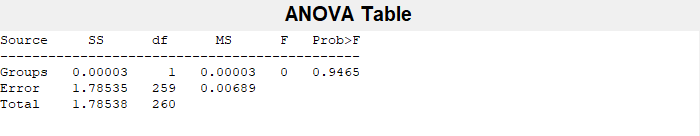

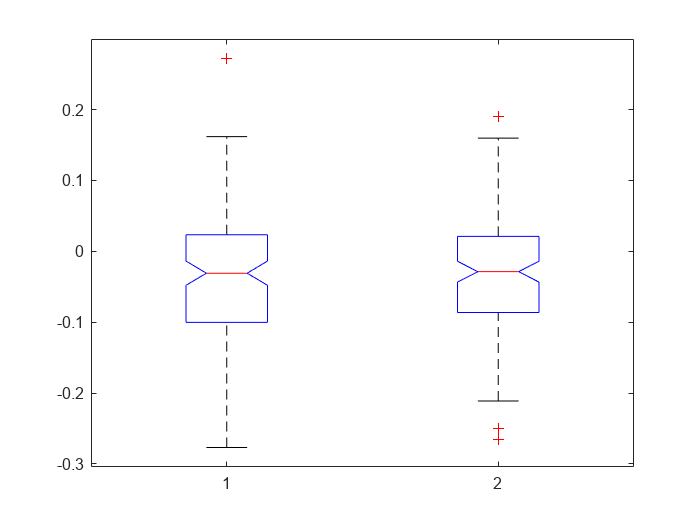

% Unificamos los datos de ambos grupos en una sola matriz POSICION
datos_posicion = [grupoA_datos_posicion; grupoB_datos_posicion];
grupos_posicion = [repmat(1, length(grupoA_datos_posicion), 1); repmat(2, length(grupoB_datos_posicion), 1)]; % 1 para Grupo A, 2 para Grupo B

% Realizamos el ANOVA
[p_p, tbl_p, stats_p] = anova1(datos_posicion, grupos_posicion); % p: valor p, tbl: tabla de resultados, stats: estadísticas adicionales

disp('Resultados del ANOVA:');

Resultados del ANOVA:


disp(tbl_p);

    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[3.1115e-05]}    {[  1]}    {[3.1115e-05]}    {[  0.0045]}    {[  0.9465]}
    {'Error' }    {[    1.7854]}    {[259]}    {[    0.0069]}    {0×0 double}    {0×0 double}
    {'Total' }    {[    1.7854]}    {[260]}    {0×0 double  }    {0×0 double}    {0×0 double}



% Unificamos los datos de ambos grupos en una sola matriz ANGULOS
datos_angulos = [grupoA_datos_angulos; grupoB_datos_angulos];
grupos_angulos = [repmat(1, length(grupoA_datos_angulos), 1); repmat(2, length(grupoB_datos_angulos), 1)]; % 1 para Grupo A, 2 para Grupo B

% Realizamos el ANOVA
[p_a, tbl_a, stats_a] = anova1(datos_posicion, grupos_posicion); % p: valor p, tbl: tabla de resultados, stats: estadísticas adicionales

disp('Resultados del ANOVA:');

Resultados del ANOVA:


disp(tbl_a);

    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[3.1115e-05]}    {[  1]}    {[3.1115e-05]}    {[  0.0045]}    {[  0.9465]}
    {'Error' }    {[    1.7854]}    {[259]}    {[    0.0069]}    {0×0 double}    {0×0 double}
    {'Total' }    {[    1.7854]}    {[260]}    {0×0 double  }    {0×0 double}    {0×0 double}



**HISTOGRAMAS Y Q-Q PLOT para la media de ángulos de cada grupo**

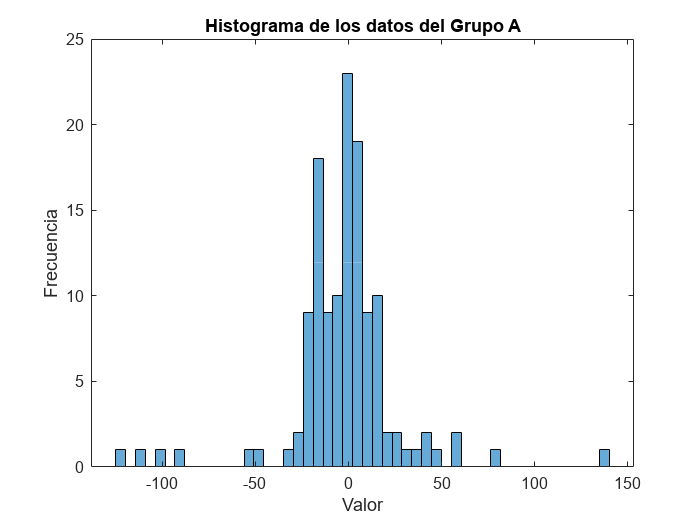

% Histograma de los datos
histogram(grupoA_datos_angulos, 50); % Ajusta el número de bins según sea necesario
title('Histograma de los datos del Grupo A');
xlabel('Valor');
ylabel('Frecuencia');

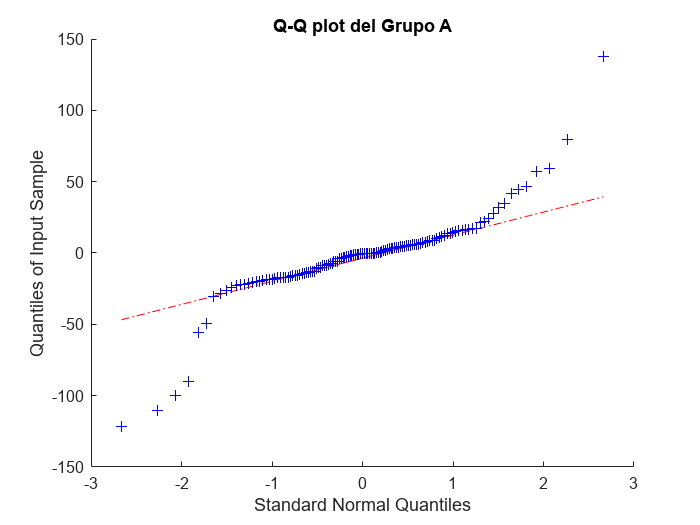

% Q-Q plot
figure;
qqplot(grupoA_datos_angulos);
title('Q-Q plot del Grupo A');

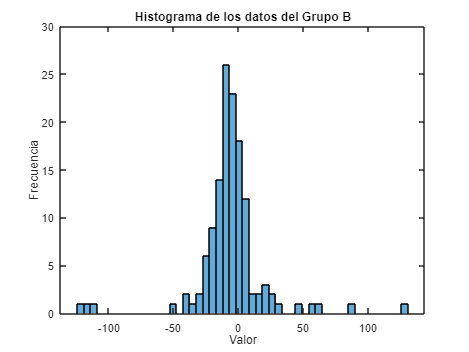

% Histograma de los datos
histogram(grupoB_datos_angulos, 50); % Ajusta el número de bins según sea necesario
title('Histograma de los datos del Grupo B');
xlabel('Valor');
ylabel('Frecuencia');

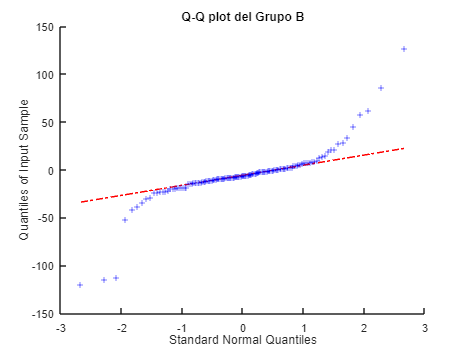

% Q-Q plot
figure;
qqplot(grupoB_datos_angulos);
title('Q-Q plot del Grupo B');

**GRÁFICAS GRUPO A POSICIÓN CENTRADAS**

%{
for i = 1:43
figure;
    % Gráfico de la posición X_A
    subplot(3, 1, 1); % Primera subgráfica
    plot(tiempo_A{i}, posicionX_A_centrada{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (ms)');
    ylabel('Posición X');
    title('Posición X respecto al tiempo de A centrada');
    % Gráfico de la posición Y_A
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_A{i}, posicionY_A_centrada{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (ms)');
    ylabel('Posición Y');
    title('Posición Y respecto al tiempo de A centrada');
    
    % Gráfico de la posición Z_A
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_A{i}, posicionZ_A_centrada{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (ms)');
    ylabel('Posición Z');
    title('Posición Z respecto al tiempo de A centrada');
end

**GRÁFICAS GRUPO B POSICIÓN CENTRADAS**

for i = 1:44
figure;
    % Gráfico de la posición X_B
    subplot(3, 1, 1); % Primera subgráfica
    plot(tiempo_B{i}, posicionX_B_centrada{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (ms)');
    ylabel('Posición X');
    title('Posición X respecto al tiempo de B centrada');
    % Gráfico de la posición Y_B
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_B{i}, posicionY_B_centrada{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (ms)');
    ylabel('Posición Y');
    title('Posición Y respecto al tiempo de B centrada');
    
    % Gráfico de la posición Z_B
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_B{i}, posicionZ_B_centrada{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (ms)');
    ylabel('Posición Z');
    title('Posición Z respecto al tiempo de B centrada');
end

**GRÁFICA GRUPO A ÁNGULOS DE EULER CENTRADA **

for i =1:43
figure;
    % Gráfico de x
    subplot(3, 1, 1); % Primera subgráfica
    plot(tiempo_A{i}, anguloEulerX_A_centrado{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Ángulo X');
    title('Ángulo X respecto al tiempo de A centrado');
    % Gráfico de y
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_A{i}, anguloEulerY_A_centrado{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Ángulo Y');
    title('Ángulo Y respecto al tiempo de A centrado');
    
    % Gráfico de z
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_A{i}, anguloEulerZ_A_centrado{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Ángulo Z');
    title('Ángulo Z respecto al tiempo de A centrado');
end

**GRÁFICA GRUPO B ÁNGULOS DE EULER CENTRADA**

for i = 1:44
figure;
    % Gráfico de x
    subplot(3, 1, 1); % Primera subgráfica
    plot(tiempo_B{i}, anguloEulerX_B_centrado{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Ángulo X');
    title('Ángulo X respecto al tiempo de B centrado');
    % Gráfico de la posición Y
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_B{i}, anguloEulerY_B_centrado{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Ángulo Y');
    title('Ángulo Y respecto al tiempo de B centrado');
    
    % Gráfico de la posición Z
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_B{i}, anguloEulerZ_B_centrado{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Ángulo Z');
    title('Ángulo Z respecto al tiempo de B centrado');
end
%}

**MÁXIMOS, MEDIA Y RANGO DE MOVIMIENTO EN CADA EJE (CENTRADO)**

for i = 1:43
    fprintf('Máximo ángulo en el eje X del grupo A: %.2f grados\n',max(anguloEulerX_A_centrado{i}));
    fprintf('Máximo ángulo en el eje Y del grupo A: %.2f grados\n',max(anguloEulerY_A_centrado{i}));
    fprintf('Máximo ángulo en el eje Z del grupo A: %.2f grados\n',max(anguloEulerZ_A_centrado{i}));
    fprintf('Ángulo medio en el eje X del grupo A: %.2f grados\n',mean(anguloEulerX_A_centrado{i}));
    fprintf('Ángulo medio en el eje Y del grupo A: %.2f grados\n',mean(anguloEulerY_A_centrado{i}));
    fprintf('Ángulo medio en el eje Z del grupo A: %.2f grados\n',mean(anguloEulerZ_A_centrado{i}));
    ROM_X_A = max(anguloEulerX_A_centrado{i}) - min(anguloEulerX_A_centrado{i}); % Rango de flexión/extensión
    ROM_Y_A = max(anguloEulerY_A_centrado{i}) - min(anguloEulerY_A_centrado{i}); % Rango de rotación
    ROM_Z_A = max(anguloEulerZ_A_centrado{i}) - min(anguloEulerZ_A_centrado{i}); % Rango de inclinación lateral
    fprintf('Rango de movimiento en el eje X del grupo A (flexión/extensión): %.2f grados\n', ROM_X_A);
    fprintf('Rango de movimiento en el eje Y del grupo A (rotación): %.2f grados\n', ROM_Y_A);
    fprintf('Rango de movimiento en el eje Z del grupo A (inclinación lateral): %.2f grados\n', ROM_Z_A);
end

Máximo ángulo en el eje X del grupo A: 77.54 grados


Máximo ángulo en el eje Y del grupo A: 179.77 grados


Máximo ángulo en el eje Z del grupo A: 130.05 grados


Ángulo medio en el eje X del grupo A: -0.55 grados


Ángulo medio en el eje Y del grupo A: 5.30 grados


Ángulo medio en el eje Z del grupo A: -7.35 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 114.49 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.84 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 199.68 grados


Máximo ángulo en el eje X del grupo A: 48.79 grados


Máximo ángulo en el eje Y del grupo A: 179.18 grados


Máximo ángulo en el eje Z del grupo A: 60.87 grados


Ángulo medio en el eje X del grupo A: 1.50 grados


Ángulo medio en el eje Y del grupo A: 16.10 grados


Ángulo medio en el eje Z del grupo A: -15.59 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 120.61 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.00 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 151.16 grados


Máximo ángulo en el eje X del grupo A: 179.46 grados


Máximo ángulo en el eje Y del grupo A: 177.88 grados


Máximo ángulo en el eje Z del grupo A: 62.61 grados


Ángulo medio en el eje X del grupo A: -110.48 grados


Ángulo medio en el eje Y del grupo A: -16.97 grados


Ángulo medio en el eje Z del grupo A: -15.83 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 358.94 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.83 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 141.85 grados


Máximo ángulo en el eje X del grupo A: 47.35 grados


Máximo ángulo en el eje Y del grupo A: 179.09 grados


Máximo ángulo en el eje Z del grupo A: 52.20 grados


Ángulo medio en el eje X del grupo A: -2.20 grados


Ángulo medio en el eje Y del grupo A: 13.32 grados


Ángulo medio en el eje Z del grupo A: -22.33 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 112.19 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.46 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 174.07 grados


Máximo ángulo en el eje X del grupo A: 86.75 grados


Máximo ángulo en el eje Y del grupo A: 178.44 grados


Máximo ángulo en el eje Z del grupo A: 44.56 grados


Ángulo medio en el eje X del grupo A: -0.32 grados


Ángulo medio en el eje Y del grupo A: -5.70 grados


Ángulo medio en el eje Z del grupo A: -13.95 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 144.16 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.44 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 160.98 grados


Máximo ángulo en el eje X del grupo A: 179.01 grados


Máximo ángulo en el eje Y del grupo A: 171.47 grados


Máximo ángulo en el eje Z del grupo A: 47.89 grados


Ángulo medio en el eje X del grupo A: -121.47 grados


Ángulo medio en el eje Y del grupo A: -22.34 grados


Ángulo medio en el eje Z del grupo A: -14.35 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 358.44 grados


Rango de movimiento en el eje Y del grupo A (rotación): 350.47 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 149.85 grados


Máximo ángulo en el eje X del grupo A: 54.71 grados


Máximo ángulo en el eje Y del grupo A: 178.51 grados


Máximo ángulo en el eje Z del grupo A: 27.74 grados


Ángulo medio en el eje X del grupo A: 3.39 grados


Ángulo medio en el eje Y del grupo A: 8.64 grados


Ángulo medio en el eje Z del grupo A: -16.55 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 90.50 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.01 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 112.59 grados


Máximo ángulo en el eje X del grupo A: 53.89 grados


Máximo ángulo en el eje Y del grupo A: 177.59 grados


Máximo ángulo en el eje Z del grupo A: 82.57 grados


Ángulo medio en el eje X del grupo A: -16.88 grados


Ángulo medio en el eje Y del grupo A: 13.44 grados


Ángulo medio en el eje Z del grupo A: -9.06 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 132.34 grados


Rango de movimiento en el eje Y del grupo A (rotación): 356.58 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 174.81 grados


Máximo ángulo en el eje X del grupo A: 42.59 grados


Máximo ángulo en el eje Y del grupo A: 179.65 grados


Máximo ángulo en el eje Z del grupo A: 69.75 grados


Ángulo medio en el eje X del grupo A: -17.07 grados


Ángulo medio en el eje Y del grupo A: 6.24 grados


Ángulo medio en el eje Z del grupo A: -1.40 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 118.06 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.84 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 149.06 grados


Máximo ángulo en el eje X del grupo A: 49.11 grados


Máximo ángulo en el eje Y del grupo A: 179.43 grados


Máximo ángulo en el eje Z del grupo A: 80.37 grados


Ángulo medio en el eje X del grupo A: -3.23 grados


Ángulo medio en el eje Y del grupo A: -11.06 grados


Ángulo medio en el eje Z del grupo A: -1.12 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 101.25 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.29 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 147.98 grados


Máximo ángulo en el eje X del grupo A: 77.86 grados


Máximo ángulo en el eje Y del grupo A: 179.24 grados


Máximo ángulo en el eje Z del grupo A: 30.96 grados


Ángulo medio en el eje X del grupo A: 3.93 grados


Ángulo medio en el eje Y del grupo A: 16.88 grados


Ángulo medio en el eje Z del grupo A: -14.35 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 117.65 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.45 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 128.41 grados


Máximo ángulo en el eje X del grupo A: 74.93 grados


Máximo ángulo en el eje Y del grupo A: 179.28 grados


Máximo ángulo en el eje Z del grupo A: 33.11 grados


Ángulo medio en el eje X del grupo A: 4.55 grados


Ángulo medio en el eje Y del grupo A: 10.58 grados


Ángulo medio en el eje Z del grupo A: -13.16 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 125.10 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.26 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 111.88 grados


Máximo ángulo en el eje X del grupo A: 82.35 grados


Máximo ángulo en el eje Y del grupo A: 176.75 grados


Máximo ángulo en el eje Z del grupo A: 61.69 grados


Ángulo medio en el eje X del grupo A: 17.00 grados


Ángulo medio en el eje Y del grupo A: 27.36 grados


Ángulo medio en el eje Z del grupo A: -8.11 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 124.78 grados


Rango de movimiento en el eje Y del grupo A (rotación): 353.19 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 148.57 grados


Máximo ángulo en el eje X del grupo A: 51.33 grados


Máximo ángulo en el eje Y del grupo A: 179.22 grados


Máximo ángulo en el eje Z del grupo A: 45.82 grados


Ángulo medio en el eje X del grupo A: -0.99 grados


Ángulo medio en el eje Y del grupo A: 58.88 grados


Ángulo medio en el eje Z del grupo A: -9.00 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 94.97 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.16 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 113.33 grados


Máximo ángulo en el eje X del grupo A: 55.36 grados


Máximo ángulo en el eje Y del grupo A: 156.21 grados


Máximo ángulo en el eje Z del grupo A: 30.13 grados


Ángulo medio en el eje X del grupo A: 4.88 grados


Ángulo medio en el eje Y del grupo A: 2.29 grados


Ángulo medio en el eje Z del grupo A: -23.09 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 117.05 grados


Rango de movimiento en el eje Y del grupo A (rotación): 328.50 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 115.18 grados


Máximo ángulo en el eje X del grupo A: 179.72 grados


Máximo ángulo en el eje Y del grupo A: 179.76 grados


Máximo ángulo en el eje Z del grupo A: 20.22 grados


Ángulo medio en el eje X del grupo A: 137.93 grados


Ángulo medio en el eje Y del grupo A: -0.31 grados


Ángulo medio en el eje Z del grupo A: -13.19 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 359.40 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.45 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 89.95 grados


Máximo ángulo en el eje X del grupo A: 80.77 grados


Máximo ángulo en el eje Y del grupo A: 179.81 grados


Máximo ángulo en el eje Z del grupo A: 120.97 grados


Ángulo medio en el eje X del grupo A: 5.95 grados


Ángulo medio en el eje Y del grupo A: 41.44 grados


Ángulo medio en el eje Z del grupo A: 1.63 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 167.65 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.68 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 225.12 grados


Máximo ángulo en el eje X del grupo A: 81.92 grados


Máximo ángulo en el eje Y del grupo A: 179.88 grados


Máximo ángulo en el eje Z del grupo A: 59.13 grados


Ángulo medio en el eje X del grupo A: 12.59 grados


Ángulo medio en el eje Y del grupo A: 16.06 grados


Ángulo medio en el eje Z del grupo A: -13.00 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 122.20 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.74 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 146.24 grados


Máximo ángulo en el eje X del grupo A: -30.32 grados


Máximo ángulo en el eje Y del grupo A: 179.42 grados


Máximo ángulo en el eje Z del grupo A: 71.71 grados


Ángulo medio en el eje X del grupo A: -89.95 grados


Ángulo medio en el eje Y del grupo A: -21.51 grados


Ángulo medio en el eje Z del grupo A: -8.63 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 126.54 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.38 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 157.08 grados


Máximo ángulo en el eje X del grupo A: 54.08 grados


Máximo ángulo en el eje Y del grupo A: 179.92 grados


Máximo ángulo en el eje Z del grupo A: 77.01 grados


Ángulo medio en el eje X del grupo A: -0.54 grados


Ángulo medio en el eje Y del grupo A: 7.10 grados


Ángulo medio en el eje Z del grupo A: 5.02 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 119.84 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.51 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 140.82 grados


Máximo ángulo en el eje X del grupo A: 66.70 grados


Máximo ángulo en el eje Y del grupo A: 175.77 grados


Máximo ángulo en el eje Z del grupo A: 38.44 grados


Ángulo medio en el eje X del grupo A: 6.25 grados


Ángulo medio en el eje Y del grupo A: 14.51 grados


Ángulo medio en el eje Z del grupo A: -18.40 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 125.18 grados


Rango de movimiento en el eje Y del grupo A (rotación): 354.56 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 143.28 grados


Máximo ángulo en el eje X del grupo A: 43.13 grados


Máximo ángulo en el eje Y del grupo A: 179.76 grados


Máximo ángulo en el eje Z del grupo A: 34.85 grados


Ángulo medio en el eje X del grupo A: -0.65 grados


Ángulo medio en el eje Y del grupo A: 11.42 grados


Ángulo medio en el eje Z del grupo A: -30.51 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 106.04 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.64 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 128.52 grados


Máximo ángulo en el eje X del grupo A: 88.42 grados


Máximo ángulo en el eje Y del grupo A: 177.35 grados


Máximo ángulo en el eje Z del grupo A: 47.82 grados


Ángulo medio en el eje X del grupo A: 8.05 grados


Ángulo medio en el eje Y del grupo A: -3.16 grados


Ángulo medio en el eje Z del grupo A: -28.22 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 143.00 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.11 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 168.61 grados


Máximo ángulo en el eje X del grupo A: 56.09 grados


Máximo ángulo en el eje Y del grupo A: 179.82 grados


Máximo ángulo en el eje Z del grupo A: 50.33 grados


Ángulo medio en el eje X del grupo A: 3.99 grados


Ángulo medio en el eje Y del grupo A: 57.10 grados


Ángulo medio en el eje Z del grupo A: -15.99 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 116.47 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.60 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 127.84 grados


Máximo ángulo en el eje X del grupo A: 77.91 grados


Máximo ángulo en el eje Y del grupo A: 179.20 grados


Máximo ángulo en el eje Z del grupo A: 133.46 grados


Ángulo medio en el eje X del grupo A: 0.12 grados


Ángulo medio en el eje Y del grupo A: -0.28 grados


Ángulo medio en el eje Z del grupo A: -6.20 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 163.03 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.85 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 220.54 grados


Máximo ángulo en el eje X del grupo A: 31.83 grados


Máximo ángulo en el eje Y del grupo A: 178.06 grados


Máximo ángulo en el eje Z del grupo A: 23.67 grados


Ángulo medio en el eje X del grupo A: -0.03 grados


Ángulo medio en el eje Y del grupo A: 14.84 grados


Ángulo medio en el eje Z del grupo A: -17.17 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 80.43 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.71 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 76.41 grados


Máximo ángulo en el eje X del grupo A: 55.62 grados


Máximo ángulo en el eje Y del grupo A: 179.74 grados


Máximo ángulo en el eje Z del grupo A: 134.39 grados


Ángulo medio en el eje X del grupo A: -1.77 grados


Ángulo medio en el eje Y del grupo A: -3.55 grados


Ángulo medio en el eje Z del grupo A: 23.89 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 95.73 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.45 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 169.84 grados


Máximo ángulo en el eje X del grupo A: 44.48 grados


Máximo ángulo en el eje Y del grupo A: 178.82 grados


Máximo ángulo en el eje Z del grupo A: 50.11 grados


Ángulo medio en el eje X del grupo A: -7.23 grados


Ángulo medio en el eje Y del grupo A: 21.81 grados


Ángulo medio en el eje Z del grupo A: -24.03 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 131.47 grados


Rango de movimiento en el eje Y del grupo A (rotación): 356.18 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 165.40 grados


Máximo ángulo en el eje X del grupo A: 69.14 grados


Máximo ángulo en el eje Y del grupo A: 179.94 grados


Máximo ángulo en el eje Z del grupo A: 135.84 grados


Ángulo medio en el eje X del grupo A: 7.68 grados


Ángulo medio en el eje Y del grupo A: -19.99 grados


Ángulo medio en el eje Z del grupo A: 16.80 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 123.13 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.50 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 154.59 grados


Máximo ángulo en el eje X del grupo A: 69.20 grados


Máximo ángulo en el eje Y del grupo A: 179.96 grados


Máximo ángulo en el eje Z del grupo A: 112.90 grados


Ángulo medio en el eje X del grupo A: 6.23 grados


Ángulo medio en el eje Y del grupo A: 31.81 grados


Ángulo medio en el eje Z del grupo A: 8.70 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 99.68 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.41 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 167.05 grados


Máximo ángulo en el eje X del grupo A: 179.93 grados


Máximo ángulo en el eje Y del grupo A: 179.34 grados


Máximo ángulo en el eje Z del grupo A: 114.78 grados


Ángulo medio en el eje X del grupo A: 79.63 grados


Ángulo medio en el eje Y del grupo A: 34.62 grados


Ángulo medio en el eje Z del grupo A: 46.76 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 359.87 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.62 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 134.29 grados


Máximo ángulo en el eje X del grupo A: 67.18 grados


Máximo ángulo en el eje Y del grupo A: 179.91 grados


Máximo ángulo en el eje Z del grupo A: 59.06 grados


Ángulo medio en el eje X del grupo A: 3.47 grados


Ángulo medio en el eje Y del grupo A: 3.73 grados


Ángulo medio en el eje Z del grupo A: -26.22 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 142.79 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.77 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 147.16 grados


Máximo ángulo en el eje X del grupo A: 40.76 grados


Máximo ángulo en el eje Y del grupo A: 179.70 grados


Máximo ángulo en el eje Z del grupo A: 40.86 grados


Ángulo medio en el eje X del grupo A: -0.66 grados


Ángulo medio en el eje Y del grupo A: -19.96 grados


Ángulo medio en el eje Z del grupo A: -15.26 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 107.74 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.50 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 105.15 grados


Máximo ángulo en el eje X del grupo A: 66.94 grados


Máximo ángulo en el eje Y del grupo A: 179.59 grados


Máximo ángulo en el eje Z del grupo A: 62.45 grados


Ángulo medio en el eje X del grupo A: 16.53 grados


Ángulo medio en el eje Y del grupo A: -16.92 grados


Ángulo medio en el eje Z del grupo A: 9.84 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 100.20 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.18 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 136.36 grados


Máximo ángulo en el eje X del grupo A: 173.09 grados


Máximo ángulo en el eje Y del grupo A: 179.61 grados


Máximo ángulo en el eje Z del grupo A: 81.03 grados


Ángulo medio en el eje X del grupo A: -100.01 grados


Ángulo medio en el eje Y del grupo A: 21.58 grados


Ángulo medio en el eje Z del grupo A: -2.61 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 352.59 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.43 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 191.44 grados


Máximo ángulo en el eje X del grupo A: 68.44 grados


Máximo ángulo en el eje Y del grupo A: 179.97 grados


Máximo ángulo en el eje Z del grupo A: 108.07 grados


Ángulo medio en el eje X del grupo A: -0.70 grados


Ángulo medio en el eje Y del grupo A: -10.31 grados


Ángulo medio en el eje Z del grupo A: -1.72 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 145.58 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.75 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 205.50 grados


Máximo ángulo en el eje X del grupo A: 46.03 grados


Máximo ángulo en el eje Y del grupo A: 175.95 grados


Máximo ángulo en el eje Z del grupo A: 32.65 grados


Ángulo medio en el eje X del grupo A: 0.62 grados


Ángulo medio en el eje Y del grupo A: 4.48 grados


Ángulo medio en el eje Z del grupo A: -17.64 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 118.95 grados


Rango de movimiento en el eje Y del grupo A (rotación): 353.51 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 110.64 grados


Máximo ángulo en el eje X del grupo A: 67.06 grados


Máximo ángulo en el eje Y del grupo A: 176.74 grados


Máximo ángulo en el eje Z del grupo A: 96.16 grados


Ángulo medio en el eje X del grupo A: 3.11 grados


Ángulo medio en el eje Y del grupo A: 6.63 grados


Ángulo medio en el eje Z del grupo A: 44.56 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 126.15 grados


Rango de movimiento en el eje Y del grupo A (rotación): 353.06 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 119.60 grados


Máximo ángulo en el eje X del grupo A: 48.99 grados


Máximo ángulo en el eje Y del grupo A: 179.44 grados


Máximo ángulo en el eje Z del grupo A: 30.26 grados


Ángulo medio en el eje X del grupo A: 1.02 grados


Ángulo medio en el eje Y del grupo A: -55.39 grados


Ángulo medio en el eje Z del grupo A: -14.00 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 100.67 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.22 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 106.35 grados


Máximo ángulo en el eje X del grupo A: 62.52 grados


Máximo ángulo en el eje Y del grupo A: 179.71 grados


Máximo ángulo en el eje Z del grupo A: 51.19 grados


Ángulo medio en el eje X del grupo A: -6.04 grados


Ángulo medio en el eje Y del grupo A: -49.17 grados


Ángulo medio en el eje Z del grupo A: -18.42 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 133.48 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.63 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 191.24 grados


Máximo ángulo en el eje X del grupo A: 62.59 grados


Máximo ángulo en el eje Y del grupo A: 179.64 grados


Máximo ángulo en el eje Z del grupo A: 95.27 grados


Ángulo medio en el eje X del grupo A: 4.92 grados


Ángulo medio en el eje Y del grupo A: 8.60 grados


Ángulo medio en el eje Z del grupo A: -18.59 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 119.29 grados


Rango de movimiento en el eje Y del grupo A (rotación): 358.41 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 182.87 grados


Máximo ángulo en el eje X del grupo A: 39.84 grados


Máximo ángulo en el eje Y del grupo A: 179.92 grados


Máximo ángulo en el eje Z del grupo A: 54.91 grados


Ángulo medio en el eje X del grupo A: -10.41 grados


Ángulo medio en el eje Y del grupo A: -0.96 grados


Ángulo medio en el eje Z del grupo A: -19.13 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 98.62 grados


Rango de movimiento en el eje Y del grupo A (rotación): 359.81 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 127.41 grados


Máximo ángulo en el eje X del grupo A: 55.07 grados


Máximo ángulo en el eje Y del grupo A: 178.03 grados


Máximo ángulo en el eje Z del grupo A: 85.87 grados


Ángulo medio en el eje X del grupo A: -3.99 grados


Ángulo medio en el eje Y del grupo A: 0.25 grados


Ángulo medio en el eje Z del grupo A: -20.38 grados


Rango de movimiento en el eje X del grupo A (flexión/extensión): 139.86 grados


Rango de movimiento en el eje Y del grupo A (rotación): 357.13 grados


Rango de movimiento en el eje Z del grupo A (inclinación lateral): 177.04 grados


for i =1:44
    fprintf('Máximo ángulo en el eje X del grupo B: %.2f grados\n',max(anguloEulerX_B_centrado{i}));
    fprintf('Máximo ángulo en el eje Y del grupo B: %.2f grados\n',max(anguloEulerY_B_centrado{i}));
    fprintf('Máximo ángulo en el eje Z del grupo B: %.2f grados\n',max(anguloEulerZ_B_centrado{i}));
    fprintf('Ángulo medio en el eje X del grupo B: %.2f grados\n',mean(anguloEulerX_B_centrado{i}));
    fprintf('Ángulo medio en el eje Y del grupo B: %.2f grados\n',mean(anguloEulerY_B_centrado{i}));
    fprintf('Ángulo medio en el eje Z del grupo B: %.2f grados\n',mean(anguloEulerZ_B_centrado{i}));
    ROM_X_B = max(anguloEulerX_B_centrado{i}) - min(anguloEulerX_B_centrado{i}); % Rango de flexión/extensión
    ROM_Y_B = max(anguloEulerY_B_centrado{i}) - min(anguloEulerY_B_centrado{i}); % Rango de rotación
    ROM_Z_B = max(anguloEulerZ_B_centrado{i}) - min(anguloEulerZ_B_centrado{i}); % Rango de inclinación lateralB
    fprintf('Rango de movimiento en el eje X del grupo B (flexión/extensión): %.2f grados\n', ROM_X_B);
    fprintf('Rango de movimiento en el eje Y del grupo B (rotación): %.2f grados\n', ROM_Y_B);
    fprintf('Rango de movimiento en el eje Z del grupo B (inclinación lateral): %.2f grados\n', ROM_Z_B);
end

Máximo ángulo en el eje X del grupo B: 73.74 grados


Máximo ángulo en el eje Y del grupo B: 178.96 grados


Máximo ángulo en el eje Z del grupo B: 130.92 grados


Ángulo medio en el eje X del grupo B: 1.34 grados


Ángulo medio en el eje Y del grupo B: 12.37 grados


Ángulo medio en el eje Z del grupo B: -19.59 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 158.01 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.68 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 220.43 grados


Máximo ángulo en el eje X del grupo B: 60.25 grados


Máximo ángulo en el eje Y del grupo B: 179.30 grados


Máximo ángulo en el eje Z del grupo B: 69.51 grados


Ángulo medio en el eje X del grupo B: 4.93 grados


Ángulo medio en el eje Y del grupo B: -1.83 grados


Ángulo medio en el eje Z del grupo B: 7.27 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 125.68 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.27 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 140.80 grados


Máximo ángulo en el eje X del grupo B: 31.61 grados


Máximo ángulo en el eje Y del grupo B: 178.03 grados


Máximo ángulo en el eje Z del grupo B: 64.95 grados


Ángulo medio en el eje X del grupo B: -2.36 grados


Ángulo medio en el eje Y del grupo B: -0.72 grados


Ángulo medio en el eje Z del grupo B: 1.11 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 93.98 grados


Rango de movimiento en el eje Y del grupo B (rotación): 357.97 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 118.45 grados


Máximo ángulo en el eje X del grupo B: 61.57 grados


Máximo ángulo en el eje Y del grupo B: 179.77 grados


Máximo ángulo en el eje Z del grupo B: 72.85 grados


Ángulo medio en el eje X del grupo B: -11.83 grados


Ángulo medio en el eje Y del grupo B: -10.60 grados


Ángulo medio en el eje Z del grupo B: 1.55 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 129.13 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.61 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 130.44 grados


Máximo ángulo en el eje X del grupo B: 33.67 grados


Máximo ángulo en el eje Y del grupo B: 174.57 grados


Máximo ángulo en el eje Z del grupo B: 69.54 grados


Ángulo medio en el eje X del grupo B: -10.89 grados


Ángulo medio en el eje Y del grupo B: 6.34 grados


Ángulo medio en el eje Z del grupo B: 2.30 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 86.69 grados


Rango de movimiento en el eje Y del grupo B (rotación): 354.42 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 105.04 grados


Máximo ángulo en el eje X del grupo B: 39.04 grados


Máximo ángulo en el eje Y del grupo B: 179.51 grados


Máximo ángulo en el eje Z del grupo B: 107.90 grados


Ángulo medio en el eje X del grupo B: -20.03 grados


Ángulo medio en el eje Y del grupo B: -8.48 grados


Ángulo medio en el eje Z del grupo B: 2.34 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 120.20 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.26 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 228.70 grados


Máximo ángulo en el eje X del grupo B: 24.71 grados


Máximo ángulo en el eje Y del grupo B: 179.95 grados


Máximo ángulo en el eje Z del grupo B: 110.71 grados


Ángulo medio en el eje X del grupo B: -18.50 grados


Ángulo medio en el eje Y del grupo B: 8.21 grados


Ángulo medio en el eje Z del grupo B: -1.67 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 102.14 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.63 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 222.81 grados


Máximo ángulo en el eje X del grupo B: 121.98 grados


Máximo ángulo en el eje Y del grupo B: 178.13 grados


Máximo ángulo en el eje Z del grupo B: 39.34 grados


Ángulo medio en el eje X del grupo B: 86.36 grados


Ángulo medio en el eje Y del grupo B: 58.13 grados


Ángulo medio en el eje Z del grupo B: -22.66 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 96.35 grados


Rango de movimiento en el eje Y del grupo B (rotación): 355.14 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 110.15 grados


Máximo ángulo en el eje X del grupo B: 55.75 grados


Máximo ángulo en el eje Y del grupo B: 177.66 grados


Máximo ángulo en el eje Z del grupo B: 41.63 grados


Ángulo medio en el eje X del grupo B: -8.29 grados


Ángulo medio en el eje Y del grupo B: -9.33 grados


Ángulo medio en el eje Z del grupo B: -10.18 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 139.53 grados


Rango de movimiento en el eje Y del grupo B (rotación): 355.55 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 150.12 grados


Máximo ángulo en el eje X del grupo B: 26.84 grados


Máximo ángulo en el eje Y del grupo B: 179.37 grados


Máximo ángulo en el eje Z del grupo B: 17.46 grados


Ángulo medio en el eje X del grupo B: -8.48 grados


Ángulo medio en el eje Y del grupo B: -19.17 grados


Ángulo medio en el eje Z del grupo B: -18.87 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 97.18 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.22 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 112.34 grados


Máximo ángulo en el eje X del grupo B: 59.71 grados


Máximo ángulo en el eje Y del grupo B: 179.35 grados


Máximo ángulo en el eje Z del grupo B: 58.10 grados


Ángulo medio en el eje X del grupo B: -3.78 grados


Ángulo medio en el eje Y del grupo B: -5.91 grados


Ángulo medio en el eje Z del grupo B: -11.79 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 135.42 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.53 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 133.83 grados


Máximo ángulo en el eje X del grupo B: 32.28 grados


Máximo ángulo en el eje Y del grupo B: 179.36 grados


Máximo ángulo en el eje Z del grupo B: 25.92 grados


Ángulo medio en el eje X del grupo B: -1.00 grados


Ángulo medio en el eje Y del grupo B: -2.41 grados


Ángulo medio en el eje Z del grupo B: -22.81 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 99.72 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.31 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 91.46 grados


Máximo ángulo en el eje X del grupo B: 70.91 grados


Máximo ángulo en el eje Y del grupo B: 179.72 grados


Máximo ángulo en el eje Z del grupo B: 88.77 grados


Ángulo medio en el eje X del grupo B: -7.34 grados


Ángulo medio en el eje Y del grupo B: 1.19 grados


Ángulo medio en el eje Z del grupo B: 4.35 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 148.02 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.20 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 183.54 grados


Máximo ángulo en el eje X del grupo B: 44.13 grados


Máximo ángulo en el eje Y del grupo B: 178.57 grados


Máximo ángulo en el eje Z del grupo B: 84.11 grados


Ángulo medio en el eje X del grupo B: -24.03 grados


Ángulo medio en el eje Y del grupo B: 26.81 grados


Ángulo medio en el eje Z del grupo B: -5.87 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 128.10 grados


Rango de movimiento en el eje Y del grupo B (rotación): 357.92 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 166.03 grados


Máximo ángulo en el eje X del grupo B: -55.16 grados


Máximo ángulo en el eje Y del grupo B: 179.77 grados


Máximo ángulo en el eje Z del grupo B: 49.30 grados


Ángulo medio en el eje X del grupo B: -112.78 grados


Ángulo medio en el eje Y del grupo B: -29.21 grados


Ángulo medio en el eje Z del grupo B: -13.27 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 120.35 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.73 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 124.37 grados


Máximo ángulo en el eje X del grupo B: 70.01 grados


Máximo ángulo en el eje Y del grupo B: 179.81 grados


Máximo ángulo en el eje Z del grupo B: 35.79 grados


Ángulo medio en el eje X del grupo B: -2.09 grados


Ángulo medio en el eje Y del grupo B: -1.64 grados


Ángulo medio en el eje Z del grupo B: -22.46 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 156.97 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.51 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 135.81 grados


Máximo ángulo en el eje X del grupo B: 54.27 grados


Máximo ángulo en el eje Y del grupo B: 177.96 grados


Máximo ángulo en el eje Z del grupo B: 50.78 grados


Ángulo medio en el eje X del grupo B: -0.94 grados


Ángulo medio en el eje Y del grupo B: -3.45 grados


Ángulo medio en el eje Z del grupo B: -24.03 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 135.87 grados


Rango de movimiento en el eje Y del grupo B (rotación): 356.14 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 142.12 grados


Máximo ángulo en el eje X del grupo B: 44.90 grados


Máximo ángulo en el eje Y del grupo B: 179.79 grados


Máximo ángulo en el eje Z del grupo B: 164.16 grados


Ángulo medio en el eje X del grupo B: -9.15 grados


Ángulo medio en el eje Y del grupo B: 5.19 grados


Ángulo medio en el eje Z del grupo B: 21.32 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 140.43 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.54 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 339.12 grados


Máximo ángulo en el eje X del grupo B: 49.23 grados


Máximo ángulo en el eje Y del grupo B: 175.23 grados


Máximo ángulo en el eje Z del grupo B: 76.95 grados


Ángulo medio en el eje X del grupo B: -8.88 grados


Ángulo medio en el eje Y del grupo B: 19.38 grados


Ángulo medio en el eje Z del grupo B: -6.79 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 103.52 grados


Rango de movimiento en el eje Y del grupo B (rotación): 353.24 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 142.71 grados


Máximo ángulo en el eje X del grupo B: 47.39 grados


Máximo ángulo en el eje Y del grupo B: 179.56 grados


Máximo ángulo en el eje Z del grupo B: 63.21 grados


Ángulo medio en el eje X del grupo B: 0.27 grados


Ángulo medio en el eje Y del grupo B: -1.25 grados


Ángulo medio en el eje Z del grupo B: -14.07 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 104.97 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.41 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 127.98 grados


Máximo ángulo en el eje X del grupo B: 75.52 grados


Máximo ángulo en el eje Y del grupo B: 178.30 grados


Máximo ángulo en el eje Z del grupo B: 90.41 grados


Ángulo medio en el eje X del grupo B: 4.28 grados


Ángulo medio en el eje Y del grupo B: -0.10 grados


Ángulo medio en el eje Z del grupo B: -14.65 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 159.09 grados


Rango de movimiento en el eje Y del grupo B (rotación): 356.46 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 162.70 grados


Máximo ángulo en el eje X del grupo B: 179.40 grados


Máximo ángulo en el eje Y del grupo B: 178.33 grados


Máximo ángulo en el eje Z del grupo B: 70.83 grados


Ángulo medio en el eje X del grupo B: -114.70 grados


Ángulo medio en el eje Y del grupo B: -18.60 grados


Ángulo medio en el eje Z del grupo B: -12.14 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 359.23 grados


Rango de movimiento en el eje Y del grupo B (rotación): 355.47 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 146.96 grados


Máximo ángulo en el eje X del grupo B: 39.63 grados


Máximo ángulo en el eje Y del grupo B: 179.86 grados


Máximo ángulo en el eje Z del grupo B: 23.67 grados


Ángulo medio en el eje X del grupo B: -8.03 grados


Ángulo medio en el eje Y del grupo B: -4.93 grados


Ángulo medio en el eje Z del grupo B: -14.32 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 114.68 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.66 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 96.97 grados


Máximo ángulo en el eje X del grupo B: 63.90 grados


Máximo ángulo en el eje Y del grupo B: 179.52 grados


Máximo ángulo en el eje Z del grupo B: 37.58 grados


Ángulo medio en el eje X del grupo B: -4.80 grados


Ángulo medio en el eje Y del grupo B: 1.09 grados


Ángulo medio en el eje Z del grupo B: -30.06 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 132.12 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.37 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 148.67 grados


Máximo ángulo en el eje X del grupo B: 60.76 grados


Máximo ángulo en el eje Y del grupo B: 179.06 grados


Máximo ángulo en el eje Z del grupo B: 43.27 grados


Ángulo medio en el eje X del grupo B: 2.49 grados


Ángulo medio en el eje Y del grupo B: 14.54 grados


Ángulo medio en el eje Z del grupo B: -13.39 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 128.01 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.90 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 128.95 grados


Máximo ángulo en el eje X del grupo B: 58.16 grados


Máximo ángulo en el eje Y del grupo B: 178.67 grados


Máximo ángulo en el eje Z del grupo B: 51.32 grados


Ángulo medio en el eje X del grupo B: -8.53 grados


Ángulo medio en el eje Y del grupo B: -9.38 grados


Ángulo medio en el eje Z del grupo B: -20.15 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 133.69 grados


Rango de movimiento en el eje Y del grupo B (rotación): 357.48 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 142.93 grados


Máximo ángulo en el eje X del grupo B: 40.13 grados


Máximo ángulo en el eje Y del grupo B: 178.39 grados


Máximo ángulo en el eje Z del grupo B: 62.27 grados


Ángulo medio en el eje X del grupo B: -9.74 grados


Ángulo medio en el eje Y del grupo B: -12.59 grados


Ángulo medio en el eje Z del grupo B: -7.27 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 112.27 grados


Rango de movimiento en el eje Y del grupo B (rotación): 357.09 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 139.19 grados


Máximo ángulo en el eje X del grupo B: 36.08 grados


Máximo ángulo en el eje Y del grupo B: 179.22 grados


Máximo ángulo en el eje Z del grupo B: 51.65 grados


Ángulo medio en el eje X del grupo B: -8.32 grados


Ángulo medio en el eje Y del grupo B: -34.29 grados


Ángulo medio en el eje Z del grupo B: -6.69 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 98.02 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.62 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 112.64 grados


Máximo ángulo en el eje X del grupo B: 63.10 grados


Máximo ángulo en el eje Y del grupo B: 179.81 grados


Máximo ángulo en el eje Z del grupo B: 82.81 grados


Ángulo medio en el eje X del grupo B: -3.26 grados


Ángulo medio en el eje Y del grupo B: -7.37 grados


Ángulo medio en el eje Z del grupo B: -13.27 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 143.00 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.70 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 189.45 grados


Máximo ángulo en el eje X del grupo B: 54.46 grados


Máximo ángulo en el eje Y del grupo B: 179.64 grados


Máximo ángulo en el eje Z del grupo B: 64.65 grados


Ángulo medio en el eje X del grupo B: -6.28 grados


Ángulo medio en el eje Y del grupo B: 0.37 grados


Ángulo medio en el eje Z del grupo B: 7.49 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 119.12 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.43 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 135.17 grados


Máximo ángulo en el eje X del grupo B: 61.72 grados


Máximo ángulo en el eje Y del grupo B: 179.93 grados


Máximo ángulo en el eje Z del grupo B: 57.18 grados


Ángulo medio en el eje X del grupo B: -1.65 grados


Ángulo medio en el eje Y del grupo B: -3.57 grados


Ángulo medio en el eje Z del grupo B: -19.08 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 126.67 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.81 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 144.18 grados


Máximo ángulo en el eje X del grupo B: 87.88 grados


Máximo ángulo en el eje Y del grupo B: 179.95 grados


Máximo ángulo en el eje Z del grupo B: 146.91 grados


Ángulo medio en el eje X del grupo B: 7.69 grados


Ángulo medio en el eje Y del grupo B: 21.11 grados


Ángulo medio en el eje Z del grupo B: -8.72 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 146.36 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.80 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 228.12 grados


Máximo ángulo en el eje X del grupo B: 57.44 grados


Máximo ángulo en el eje Y del grupo B: 179.87 grados


Máximo ángulo en el eje Z del grupo B: 49.89 grados


Ángulo medio en el eje X del grupo B: -0.75 grados


Ángulo medio en el eje Y del grupo B: -9.37 grados


Ángulo medio en el eje Z del grupo B: -22.06 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 136.56 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.43 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 139.77 grados


Máximo ángulo en el eje X del grupo B: 35.32 grados


Máximo ángulo en el eje Y del grupo B: 179.66 grados


Máximo ángulo en el eje Z del grupo B: 40.64 grados


Ángulo medio en el eje X del grupo B: -5.78 grados


Ángulo medio en el eje Y del grupo B: -9.08 grados


Ángulo medio en el eje Z del grupo B: -4.52 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 100.05 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.01 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 109.03 grados


Máximo ángulo en el eje X del grupo B: 60.93 grados


Máximo ángulo en el eje Y del grupo B: 179.90 grados


Máximo ángulo en el eje Z del grupo B: 179.88 grados


Ángulo medio en el eje X del grupo B: -7.90 grados


Ángulo medio en el eje Y del grupo B: -10.65 grados


Ángulo medio en el eje Z del grupo B: -5.67 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 140.38 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.20 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 359.30 grados


Máximo ángulo en el eje X del grupo B: 44.63 grados


Máximo ángulo en el eje Y del grupo B: 179.97 grados


Máximo ángulo en el eje Z del grupo B: 63.80 grados


Ángulo medio en el eje X del grupo B: -5.96 grados


Ángulo medio en el eje Y del grupo B: -38.32 grados


Ángulo medio en el eje Z del grupo B: -4.56 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 114.37 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.97 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 119.87 grados


Máximo ángulo en el eje X del grupo B: 78.66 grados


Máximo ángulo en el eje Y del grupo B: 179.81 grados


Máximo ángulo en el eje Z del grupo B: 58.14 grados


Ángulo medio en el eje X del grupo B: 7.48 grados


Ángulo medio en el eje Y del grupo B: 28.70 grados


Ángulo medio en el eje Z del grupo B: -13.83 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 114.11 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.46 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 144.03 grados


Máximo ángulo en el eje X del grupo B: 90.28 grados


Máximo ángulo en el eje Y del grupo B: 179.88 grados


Máximo ángulo en el eje Z del grupo B: 54.18 grados


Ángulo medio en el eje X del grupo B: 45.23 grados


Ángulo medio en el eje Y del grupo B: 33.09 grados


Ángulo medio en el eje Z del grupo B: -12.05 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 106.33 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.86 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 111.98 grados


Máximo ángulo en el eje X del grupo B: 12.62 grados


Máximo ángulo en el eje Y del grupo B: 176.53 grados


Máximo ángulo en el eje Z del grupo B: 34.28 grados


Ángulo medio en el eje X del grupo B: -41.61 grados


Ángulo medio en el eje Y del grupo B: 61.32 grados


Ángulo medio en el eje Z del grupo B: -6.85 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 117.82 grados


Rango de movimiento en el eje Y del grupo B (rotación): 355.29 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 89.83 grados


Máximo ángulo en el eje X del grupo B: 179.73 grados


Máximo ángulo en el eje Y del grupo B: 179.94 grados


Máximo ángulo en el eje Z del grupo B: 21.12 grados


Ángulo medio en el eje X del grupo B: -120.15 grados


Ángulo medio en el eje Y del grupo B: 9.54 grados


Ángulo medio en el eje Z del grupo B: -13.60 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 358.98 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.70 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 79.09 grados


Máximo ángulo en el eje X del grupo B: 50.90 grados


Máximo ángulo en el eje Y del grupo B: 177.20 grados


Máximo ángulo en el eje Z del grupo B: 41.96 grados


Ángulo medio en el eje X del grupo B: 2.18 grados


Ángulo medio en el eje Y del grupo B: -5.20 grados


Ángulo medio en el eje Z del grupo B: -11.84 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 97.07 grados


Rango de movimiento en el eje Y del grupo B (rotación): 354.42 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 111.21 grados


Máximo ángulo en el eje X del grupo B: 65.35 grados


Máximo ángulo en el eje Y del grupo B: 179.70 grados


Máximo ángulo en el eje Z del grupo B: 68.82 grados


Ángulo medio en el eje X del grupo B: 4.09 grados


Ángulo medio en el eje Y del grupo B: -11.66 grados


Ángulo medio en el eje Z del grupo B: 8.18 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 134.79 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.64 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 124.37 grados


Máximo ángulo en el eje X del grupo B: 173.11 grados


Máximo ángulo en el eje Y del grupo B: 179.95 grados


Máximo ángulo en el eje Z del grupo B: 28.74 grados


Ángulo medio en el eje X del grupo B: 126.87 grados


Ángulo medio en el eje Y del grupo B: -52.55 grados


Ángulo medio en el eje Z del grupo B: -18.63 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 94.49 grados


Rango de movimiento en el eje Y del grupo B (rotación): 359.39 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 115.57 grados


Máximo ángulo en el eje X del grupo B: 63.58 grados


Máximo ángulo en el eje Y del grupo B: 179.96 grados


Máximo ángulo en el eje Z del grupo B: 21.41 grados


Ángulo medio en el eje X del grupo B: -0.05 grados


Ángulo medio en el eje Y del grupo B: 14.11 grados


Ángulo medio en el eje Z del grupo B: -13.48 grados


Rango de movimiento en el eje X del grupo B (flexión/extensión): 106.84 grados


Rango de movimiento en el eje Y del grupo B (rotación): 358.58 grados


Rango de movimiento en el eje Z del grupo B (inclinación lateral): 83.33 grados


**CÁLCULO DE LAS VELOCIDADES Y ACELERACIONES**

dt = (1/50) %Periodo de muestreo = 20ms

dt = 0.0200

%La velocidad es la primera derivada y la aceleración la segunda derivada
for i = 1:43
    velocidad_X_A{i} = diff(posicionX_A_centrada{i})/dt;
    velocidad_Y_A{i} = diff(posicionY_A_centrada{i})/dt;
    velocidad_Z_A{i} = diff(posicionZ_A_centrada{i})/dt;
    aceleracion_X_A{i} = diff(velocidad_X_A{i})/dt;
    aceleracion_Y_A{i} = diff(velocidad_Y_A{i})/dt;
    aceleracion_Z_A{i} = diff(velocidad_Z_A{i})/dt;
end
for i =1:44  
    velocidad_X_B{i} = diff(posicionX_B_centrada{i})/dt;
    velocidad_Y_B{i} = diff(posicionY_B_centrada{i})/dt;
    velocidad_Z_B{i} = diff(posicionZ_B_centrada{i})/dt;
    aceleracion_X_B{i} = diff(velocidad_X_B{i})/dt;
    aceleracion_Y_B{i} = diff(velocidad_Y_B{i})/dt;
    aceleracion_Z_B{i} = diff(velocidad_Z_B{i})/dt;
end

**FILTRADO A 10 Hz DE LAS VELOCIDADES Y ACELERACIONES**

% Parámetros del filtro
fs = 50;  % Frecuencia de muestreo (Hz)
fc = 20;  % Frecuencia de corte (Hz) 
orden = 2;  % Orden del filtro 
%inicialmente con fc=10 y orden=4 perdía mucha info en el filtrado por lo
%que he aumentado fc y disminuido el orden

% Diseño del filtro Butterworth
%[b,a] = cheby1(orden,0.05,fc/(fs/2), 'low') esta opción es bastante
%similar
[b, a] = butter(orden, fc/(fs/2), 'low');
% Aplicar el filtro a las velocidades
for i = 1:43
    velocidad_X_A_filtrada{i} = filtfilt(b, a, velocidad_X_A{i});
    velocidad_Y_A_filtrada{i} = filtfilt(b, a, velocidad_Y_A{i});
    velocidad_Z_A_filtrada{i} = filtfilt(b, a, velocidad_Z_A{i});
    aceleracion_X_A_filtrada{i} = diff(velocidad_X_A_filtrada{i})/dt;
    aceleracion_Y_A_filtrada{i} = diff(velocidad_Y_A_filtrada{i})/dt;
    aceleracion_Z_A_filtrada{i} = diff(velocidad_Z_A_filtrada{i})/dt;
end
for i = 1:44
    velocidad_X_B_filtrada{i} = filtfilt(b, a, velocidad_X_B{i});
    velocidad_Y_B_filtrada{i} = filtfilt(b, a, velocidad_Y_B{i});
    velocidad_Z_B_filtrada{i} = filtfilt(b, a, velocidad_Z_B{i});
    aceleracion_X_B_filtrada{i} = diff(velocidad_X_B_filtrada{i})/dt;
    aceleracion_Y_B_filtrada{i} = diff(velocidad_Y_B_filtrada{i})/dt;
    aceleracion_Z_B_filtrada{i} = diff(velocidad_Z_B_filtrada{i})/dt;
end

**GRÁFICA VELOCIDAD FILTRADA GRUPO A **

%{
for i = 1:43
figure;
    % Gráfico en X
    subplot(3, 1, 1); 
    plot(tiempo_A{i}(1:end-1), velocidad_X_A_filtrada{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Velocidad X (m/s)');
    title('Velocidad filtrada en X respecto al tiempo de A');
    % Gráfico en Y
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_A{i}(1:end-1), velocidad_Y_A_filtrada{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Velocidad Y (m/s)');
    title('Velocidad filtrada en Y respecto al tiempo de A');
    
    % Gráfico en Z
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_A{i}(1:end-1), velocidad_Z_A_filtrada{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Velocidad Z (m/s)');
    title('Velocidad filtrada en Z respecto al tiempo de A');
end

**GRÁFICA VELOCIDAD FILTRADA GRUPO B**

for i = 1:44
figure;
    % Gráfico en X
    subplot(3, 1, 1); 
    plot(tiempo_B{i}(1:end-1), velocidad_X_B_filtrada{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Velocidad X (m/s)');
    title('Velocidad filtrada en X respecto al tiempo de B');
    % Gráfico en Y
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_B{i}(1:end-1), velocidad_Y_B_filtrada{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Velocidad Y (m/s)');
    title('Velocidad filtrada en Y respecto al tiempo de B');
    
    % Gráfico en Z
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_B{i}(1:end-1), velocidad_Z_B_filtrada{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Velocidad Z (m/s)');
    title('Velocidad filtrada en Z respecto al tiempo de B');
end

**GRÁFICA DE ACELERACIÓN FILTRADA GRUPO A**

for i = 1:43
figure;
    % Gráfico en X
    subplot(3, 1, 1); 
    plot(tiempo_A{i}(1:end-2), aceleracion_X_A_filtrada{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Aceleracion X (m2/s)');
    title('Aceleracion en X filtrada respecto al tiempo de A');
    % Gráfico en Y
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_A{i}(1:end-2), aceleracion_Y_A_filtrada{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Aceleracion Y (m2/s)');
    title('Aceleracion en Y filtrada respecto al tiempo de A');
    
    % Gráfico en Z
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_A{i}(1:end-2), aceleracion_Z_A_filtrada{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Aceleracion Z (m2/s)');
    title('Aceleracion en Z filtrada respecto al tiempo de A');
end

**GRÁFICA DE ACELERACIÓN FILTRADA GRUPO B**

for i = 1:44
figure;
    % Gráfico en X
    subplot(3, 1, 1); 
    plot(tiempo_B{i}(1:end-2), aceleracion_X_B_filtrada{i}, 'r-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Aceleracion X (m2/s)');
    title('Aceleracion en X filtrada respecto al tiempo de B');
    % Gráfico en Y
    subplot(3, 1, 2); % Segunda subgráfica
    plot(tiempo_B{i}(1:end-2), aceleracion_Y_B_filtrada{i}, 'g-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Aceleracion Y (m2/s)');
    title('Aceleracion en Y filtrada respecto al tiempo de B');
    
    % Gráfico en Z
    subplot(3, 1, 3); % Tercera subgráfica
    plot(tiempo_B{i}(1:end-2), aceleracion_Z_B_filtrada{i}, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Aceleracion Z (m2/s)');
    title('Aceleracion en Z filtrada respecto al tiempo de B');
end
%}

### **EXPORTACIÓN DE LOS DATOS A UN CSV**

**CREO UNA TABLA CON TODOS LOS DATOS FILTRADOS (SOLO INFO DE 'H' Y QUITANDO PRIMERAS CELDAS SIN DATOS)  DEL GRUPO A Y B**

% Inicializar una tabla vacía para almacenar todos los datos
tablaAB = table();

% Recorrer todas las tablas de los pacientes 
for i = 1:43
    % Filtrar los datos para cada paciente (en este caso, "datosFiltradosA{i}")
    tabla_paciente_A = datosFiltradosA{i};
    
    % Crear una columna nueva que identifique al paciente
    paciente_columna = repmat(i, height(tabla_paciente_A), 1);  % Asignar el número del paciente
    
    % Añadir la columna de paciente a la tabla
    tabla_paciente_A.Paciente = paciente_columna;

    % Crear una columna que identifique el grupo (Grupo A)
    grupo_columna = repmat('A', height(tabla_paciente_A), 1);  % Asignar el grupo 'A'
    tabla_paciente_A.Grupo = grupo_columna;
    
    % Concatenar los datos de este paciente con todos los demás
    tablaAB = [tablaAB; tabla_paciente_A];  % Concatenar por filas
end

% Recorrer todas las tablas de los pacientes 
for i = 1:44
    % Filtrar los datos para cada paciente (en este caso, "datosFiltradosA{i}")
    tabla_paciente_B = datosFiltradosB{i};
    
    % Crear una columna nueva que identifique al paciente
    paciente_columna = repmat(i+43, height(tabla_paciente_B), 1);  % Asignar el número del paciente
    
    % Añadir la columna de paciente a la tabla
    tabla_paciente_B.Paciente = paciente_columna;

     % Crear una columna que identifique el grupo (Grupo B)
    grupo_columna = repmat('B', height(tabla_paciente_B), 1);  % Asignar el grupo 'B'
    tabla_paciente_B.Grupo = grupo_columna;

    % Concatenar los datos del paciente del Grupo B con todos los demás
    tablaAB = [tablaAB; tabla_paciente_B];  % Concatenar por filas
end

% Guardar en un csv esta tabla que contiene los datos iniciales
writetable(tablaAB, 'tablaAB_inicial.csv');

**CREO UNA TABLA CON TODOS LOS PACIENTES (GRUPO A Y B) **

**Esta tabla contiene todos los datos de tiempo, posicion, ángulos, velocidades, aceleraciones en cada eje y centrados además de métricas como media de los ángulos y ROM**

% Inicializar una tabla vacía para almacenar todos los datos de ambos grupos
tabla_completa = table();

% Recorrer los 43 pacientes del Grupo A
for i = 1:43
    % Crear una tabla para los datos del paciente i del Grupo A
    paciente_columna = repmat(i, length(tiempo_A{i}), 1);  % Número del paciente
    grupo_columna = repmat('A', length(tiempo_A{i}), 1);  % Indicar que es del Grupo A
    
    % Obtener los datos del paciente i del Grupo A
    tiempo = tiempo_A{i};
    posicionX = posicionX_A_centrada{i};
    posicionY = posicionY_A_centrada{i};
    posicionZ = posicionZ_A_centrada{i};
    anguloEulerX = anguloEulerX_A_centrado{i};
    anguloEulerY = anguloEulerY_A_centrado{i};
    anguloEulerZ = anguloEulerZ_A_centrado{i};

    
    % Crear la tabla del paciente del Grupo A
    tabla_paciente_A = table(paciente_columna, grupo_columna, tiempo, ...
                              posicionX, posicionY, posicionZ, ...
                              anguloEulerX, anguloEulerY, anguloEulerZ);
    
    % Concatenar los datos del paciente del Grupo A
    tabla_completa = [tabla_completa; tabla_paciente_A];
end
% Recorrer los 44 pacientes del Grupo B
for i = 1:44
    % Crear una tabla para los datos del paciente i del Grupo B
    paciente_columna = repmat(i+43, length(tiempo_B{i}), 1);  % Número del paciente
    grupo_columna = repmat('B', length(tiempo_B{i}), 1);  % Indicar que es del Grupo B
    
    % Obtener los datos del paciente i del Grupo B
    tiempo = tiempo_B{i};
    posicionX = posicionX_B_centrada{i};
    posicionY = posicionY_B_centrada{i};
    posicionZ = posicionZ_B_centrada{i};
    anguloEulerX = anguloEulerX_B_centrado{i};
    anguloEulerY = anguloEulerY_B_centrado{i};
    anguloEulerZ = anguloEulerZ_B_centrado{i};
    
    % Crear la tabla del paciente del Grupo B
    tabla_paciente_B = table(paciente_columna, grupo_columna, tiempo, ...
                              posicionX, posicionY, posicionZ, ...
                              anguloEulerX, anguloEulerY, anguloEulerZ);
    
    % Concatenar los datos del paciente del Grupo B
    tabla_completa = [tabla_completa; tabla_paciente_B];
end

% Ahora 'tabla_completa' contiene los datos de todos los pacientes del Grupo A y Grupo B
% Guardar los datos combinados en un archivo CSV
writetable(tabla_completa, 'tablagrupos_AB.csv');